clear;clc;close all;

**OFDM Parameters**

nfft = 1024;                    % nfft size equal to number of subcarriers
BW = 25000;                % Bandwidth of subcarriers (-F/2 F/2)
M = 64;                          % Baseband modulation order
Fc = 120000;                    % Center Frequency of OFDM signal
Fs = 400000;                    % Sample frequency of upsampler => Interpolator => mixer
cp_len = nfft/4;                % Cyclic Prefix length
ofdm_symbols =  1;               % Number of ofdm symbols to transmit
dac_rate = 10000000;            % DAC fixed sample rate
filt1_len = 128;                % Length of 1st Interpolation Filter
ebno_test = -5:2:30;
symbol_plot = 4;
rep = 4;                        % Repetition of pilots
interp = Fs/BW           % Interpolation factor

interp = 16

interp_dac = dac_rate/Fc; % 2nd Interpolation factor
pilot_index = [112:rep:913];    % Insert a pilot every 5 data sub-carriers
pilot_val = -0.7072+0.7072i;    % Set value of pilot subcarriers
data_index = 1:nfft;            % Index of data subcarriers
cw_tone = BW/nfft;
set_cw = 0; 
snr = 20;
% Set 224 zero padded subcarriers: 111 on lower and upper subcarriers
% and 2 on each side of carrier
zp_index = [1:111,914:1024];
multipath = [0 1 0.02 0.8];            % Multipath taps
no_multi = [1 0 0 0];
%multipath = [1 0.3 0.5 0];
data_index([zp_index,pilot_index]) = [];
scs = BW/nfft;
zp_BW = 110*scs;
cfo = 0;
cfo = linspace(-cfo,cfo,ofdm_symbols);
%cfo = cfo*ones(1,ofdm_symbols);
plot_v = 0;
plot_symbol = 1;
pilot_carriers = length(pilot_index);   % Number of pilot carriers
nfft_time = 4*2^nextpow2(nfft + cp_len);
F=(-nfft_time/2:nfft_time/2-1)/nfft_time*BW;   % Actual frequency F
F1 = (-nfft/2:nfft/2-1)/nfft*BW;

num_data_bits = length(data_index)*ofdm_symbols

num_data_bits = 601

**Modulate:**

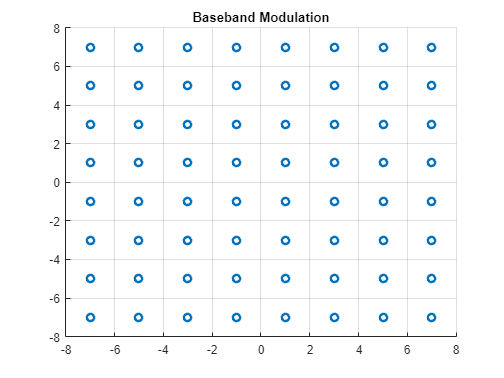

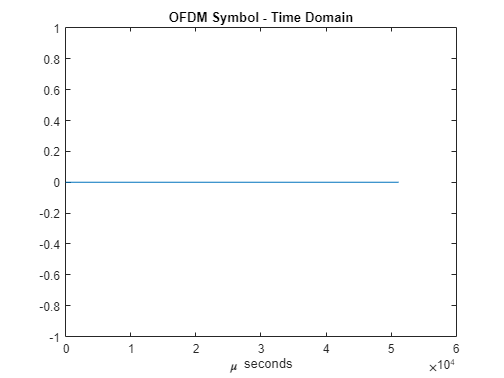

[ofdm_signal_1,reference_pilot,mod_data,t,t2,freq_data]=ofdm_transmit(nfft,BW,M,cp_len, ...
    ofdm_symbols,zp_index,pilot_index,1,1,0);

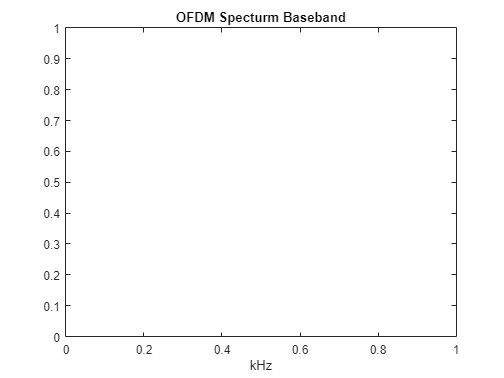

ofdm_signal_11 = ofdm_signal_1;
ofdm_signal_11(1:cp_len) = [];
ofdm_signal_freq = fftshift(fft(ofdm_signal_11,nfft));
figure(),plot(F1/1000,20*log10(abs(ofdm_signal_freq'))),title('OFDM Specturm Baseband'),xlabel('kHz')

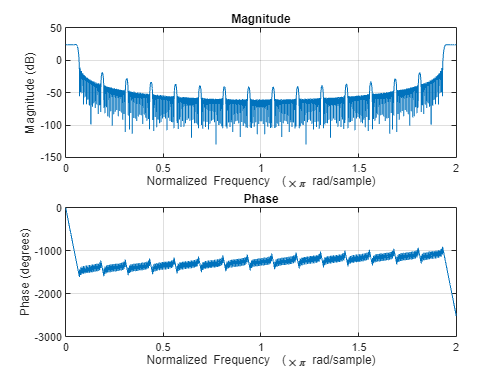

t_signal_cp = 0:1/Fs:(nfft+cp_len)*interp/Fs-1/Fs;
t_signal = 0:1/Fs:nfft*interp/Fs-1/Fs;
fc_signal = cos(2*pi*Fc*t_signal)+1j*sin(2*pi*Fc*t_signal);
up_signal = upsample(ofdm_signal_11,interp);
nfft_time2 = nfft*interp;
F2 = (-nfft_time2/2:nfft_time2/2-1)/nfft_time2*BW*interp;   % Actual frequency F
ofdm_signal_up_freq = fftshift(fft(up_signal,nfft_time2));
b = intfilt(interp,8,0.9);
B = fftshift(freqz(b,1,nfft_time2,'whole'));
N = 256;
Rp = 0.00057565;
Rst = 0.001;
b_lo = firceqrip(N,(BW-zp_BW)/(Fs),[Rp Rst],'passedge');
B_lo = fftshift(freqz(b_lo,1,nfft_time2,'whole'));
figure(),freqz(b,1,nfft_time2,'whole')

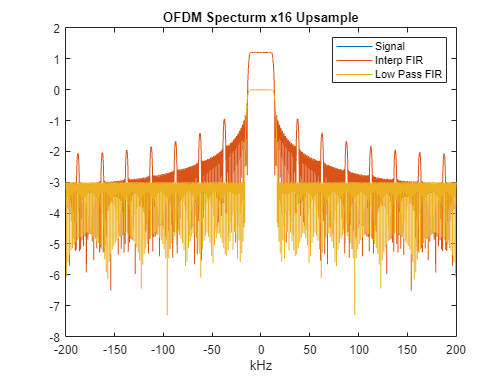

figure(),plot(F2/1000,log10(abs(ofdm_signal_up_freq'))),hold on,plot(F2/1000,log10(abs(B)))
hold on,plot(F2/1000,log10(abs(B_lo)))
legend('Signal','Interp FIR','Low Pass FIR'),title(['OFDM Specturm x',num2str(interp),' Upsample']),xlabel('kHz')

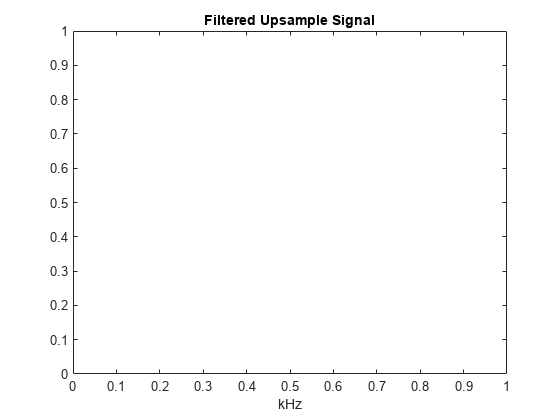

filt_signal = conv(b,up_signal);
%filt_signal = filt_signal(floor(length(b_lo)/2):end-floor(length(b_lo/2)));
filt_signal = filter(b_lo,1,up_signal);
filt_signal_freq = fftshift(fft(filt_signal,nfft_time2));
figure(),plot(F2/1000,log10(abs(filt_signal_freq))),xlabel('kHz'),title('Filtered Upsample Signal')

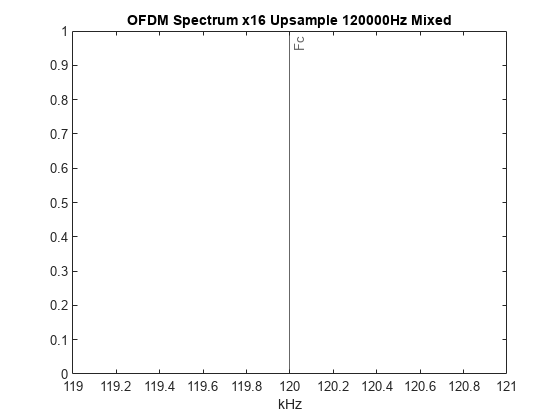

mixed_signal = filt_signal' .* fc_signal;
%mixed_signal = real(filt_signal') .* real(fc_signal);
mixed_signal_freq = fftshift(fft(mixed_signal,nfft_time2));
figure(),plot(F2/1000,log10(abs(mixed_signal_freq))),title(['OFDM Spectrum x',num2str(interp),' Upsample ',num2str(Fc),'Hz Mixed'])
xlabel('kHz'),xline([Fc/1000],'-',{'Fc'})

interp_signal = conv(b,conj(up_signal));
interp_signal = interp_signal(length(b)/2:end-length(b)/2);

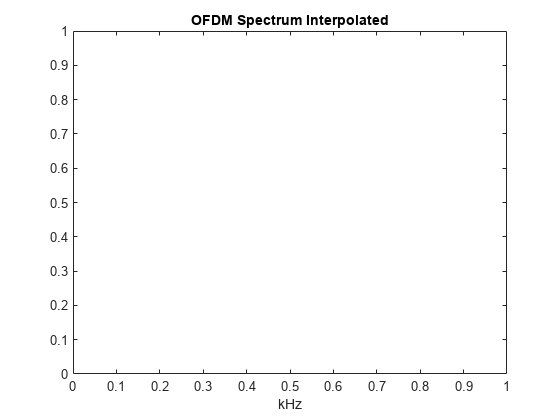

ofdm_signal_interp_freq = fftshift(fft(interp_signal,nfft_time2));
figure(),plot(F2,log10(abs(ofdm_signal_interp_freq'))),title('OFDM Spectrum Interpolated'),xlabel('kHz')